# **Tutorial 6**: a 6 dofs robotic arm on a chaser spacecraft ( $\approx 3\;mn$ run).

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

The objective is to compute the $36\times 12$ dynamic model $[\mathbf D_B^{\mathcal{S}}]_{\mathcal R_b}(\mathrm s,\mathbf\theta)$ of the system $\mathcal{S=B+A}$depicted  in the following Figure and composed of:

- the main body $\mathcal B$ (chaser spacecraft) with its center of gravity $B$, its reference point $O_b$ and its body frame $\mathcal R_b$,

- a 6 d.o.fs robotic arm $\mathcal A$, itself composed of 6 links $\mathcal L_i$, $i=1,\cdots,6$.  For each link $i$: $O_i$, $A_i$, $P_{1_i}$, $P_{2_i}$ $\mathbf x_{i}$ are (i) the reference point, (ii) the center of mass, (iii) the connection point with the parent body, (iv) the connection with the child body and (v) the joint axis direction (3 components vector ) of the revolute joint at the point $P_{1_i}$, respectively.

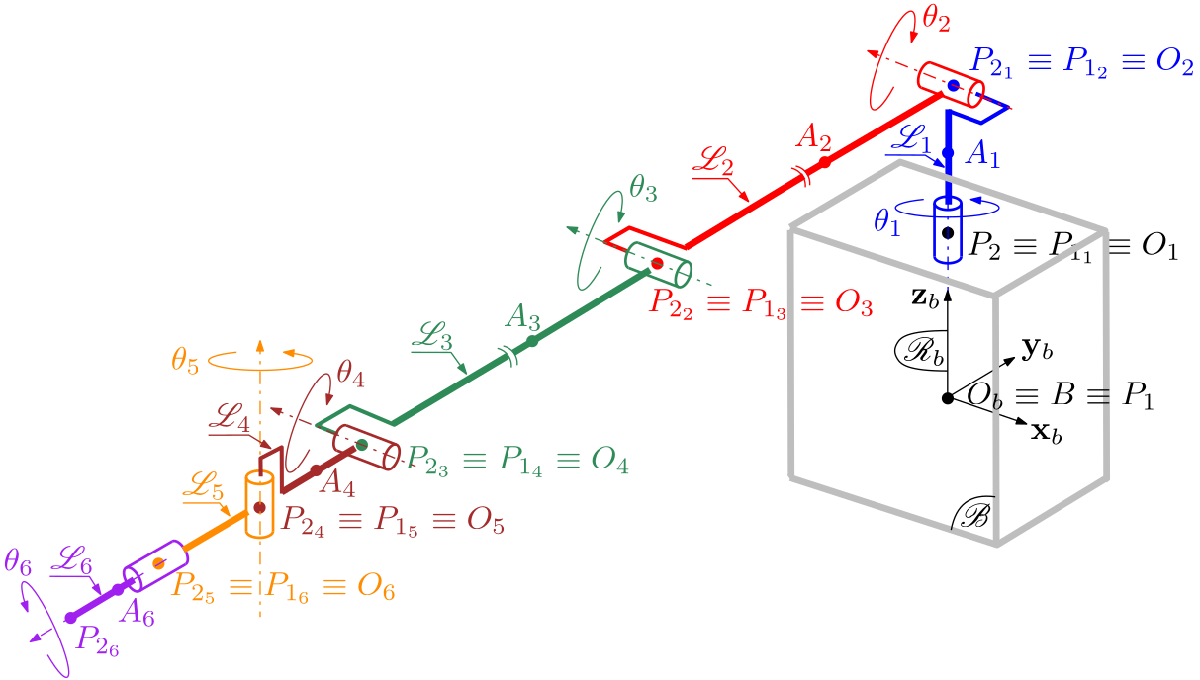

$\mathbf \theta=[\theta_1,\;\;\theta_2,\;\;\theta_3,\;\;\theta_4,\;\;\theta_5,\;\;\theta_6]^T$is the vector of the arm angular configuration. 

$[\mathbf D_B^{\mathcal{S}}]_{\mathcal R_b}(\mathrm s,\mathbf\theta)$ is the model of the system at the centre of gravity $B$ of the main body $\mathcal B$and projected in the main body frame $\mathcal R_b$ for a given angular configuration $\mathbf\theta$, that is the $36\times 12$ transfer from:

- the resultant external wrench $[\mathbf W_{ext/\mathcal B,B}]_{\mathcal R_b}$ (6 components: 3 forces and 3 torques) applied to $\mathcal B$ at the point $B$,

- 6 component input vector $\mathbf u=[u_1,\;\;u_2,\;\;u_3,\;\;u_4,\;\;u_5,\;\;,u_6]^T$ of the local torques applied inside the arm joints,

to

- the [motion vector](matlab:open('../SDTfct/doc_SDTlib/doc_BODIES/doc_hub/DocGeneralNotations.html')) of point $B$ $[\delta\mathbf m^{\mathcal B}_{P_1}]_{\mathcal R_b}$ (18 components = 6 DoFs accelerations , 6 DoFs velocities and 6 DoFs positions),

- the $6$ relative motion vectors  $\delta\mathbf m_{r_i} =[\ddot\theta_i,\;\;\delta\dot\theta_i,\;\;\delta\theta_i]^T$ of the $6$ revolute joints $i=1,\cdots 6$ between  $\mathcal L_i$ and $\mathcal L_{i-1}$ around $\mathbf x_{_i}$ (with $\mathcal L_0=\mathcal B$).

This model is a $24$-th order system and includes the $12$ rigid modes of the spacecraft, free to move along the $6$ DoFs, and the 6 revolute joints.

Then one will derive the $12\times 12$ mass matrix $[\mathbf M_B^{\mathcal{S}}]_{\mathcal R_b}(\mathbf\theta)$ of the spacecraft at the main body center of mass $B$ and projected in the main body frame $\mathcal R_b$.

## 2. Required data.

### Data relative to the main body $\mathcal B$:

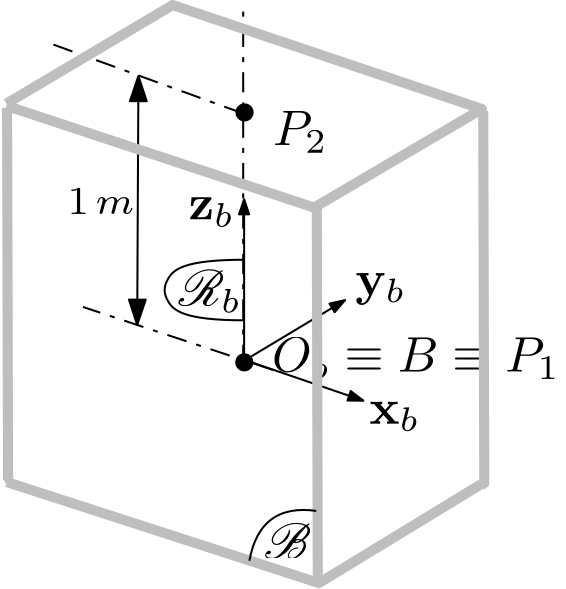

All the data are expressed in the body frame $\mathcal{R}_b$:

- geometry (in $m$): $[\vec{OP_2}]_{\mathcal R_b}=[0.\quad 0.\quad 1.]^T$,  ( $P_1\equiv B \equiv O_b$ ),

- mass: $m^{\mathcal B}=1000\,(Kg)$,

- 3x3 inertia tensor at $B$: $[\mathbf J_B^{\mathcal B}]_{\mathcal R_b}=\left[\begin{array}{ccc} 666.7 & 0 & 0 \\ 0 &666.7 & 0\\ 0 & 0 & 666.7\end{array}\right]$ ($Kg\,m^2$).

Exactly as for the[ ***tutorial 2***](matlab:open('../Tutorial2/tutorial2.html')), this body can be simply modeled with the block `multi port free rigid body` of the sub-library `6 dof bodies` of the` SDTlib`. The dialog box allows to choose 2 ports and to fill all the data:

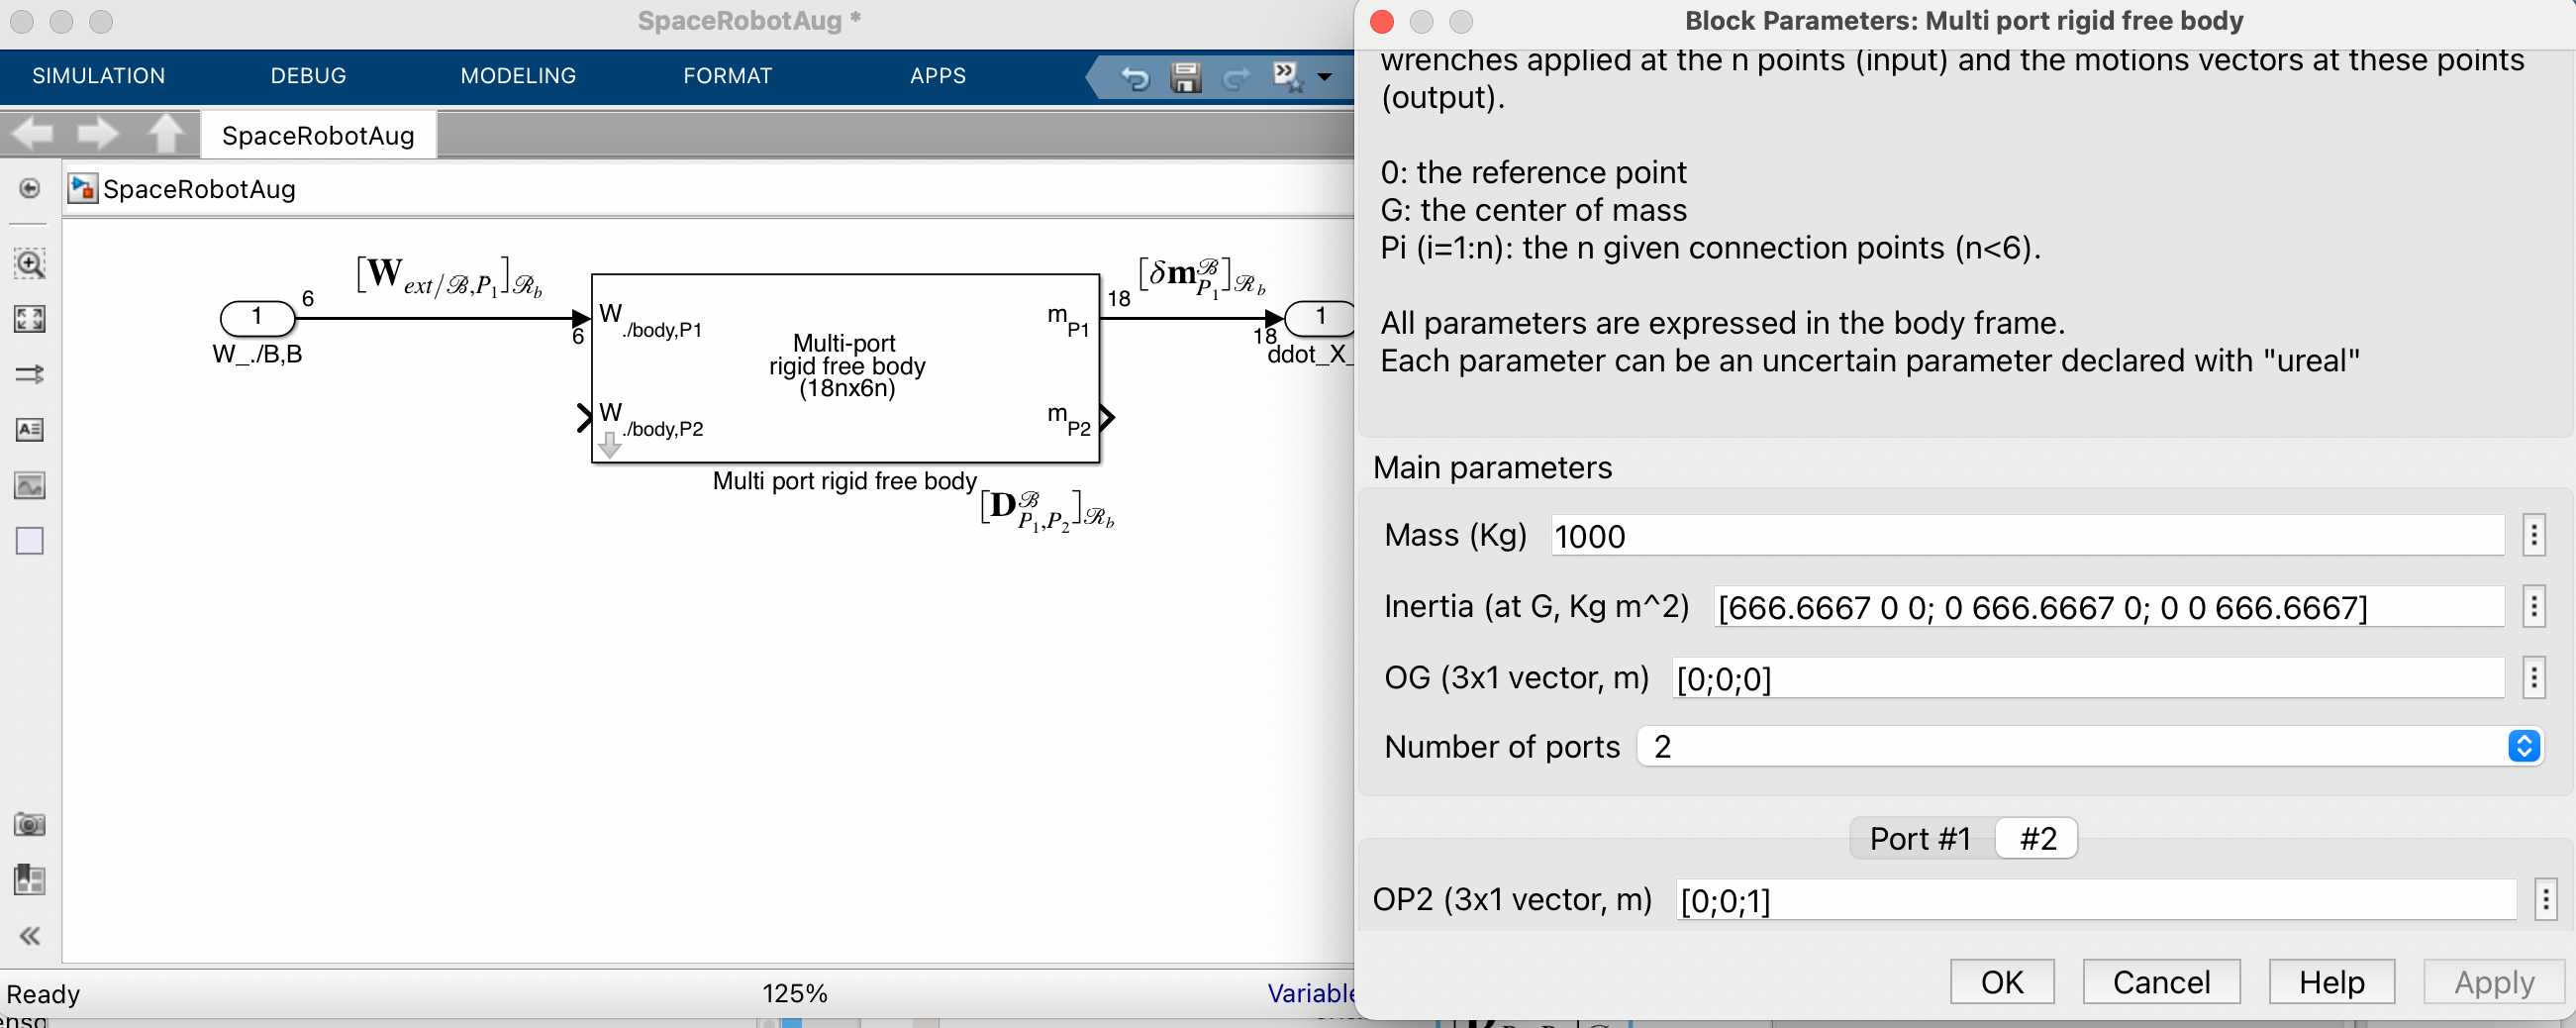

The inline `help `in the dialog box opens the web browser and describes the mathematical model $[\mathbf D^{\mathcal B}_{P_1,P_2}]$ of this block (internet connection required).  This help is also avalaible by:

web Docmultiportrigidbase.html -new

### Data relative to each link $\mathcal L_i$

First, all the links $\mathcal L_i$ are assumed to be rigid.

In the nominal configuration ( $\theta_i=0,\;\forall i$), all the data for each link can be easily expressed in the inherit frame $\mathcal{R}_b$ attached to the chaser (see Figure).

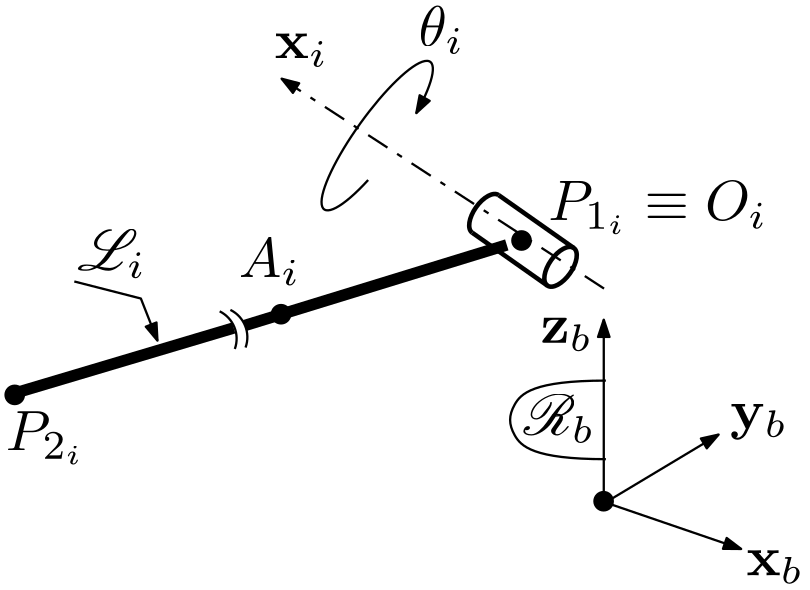


$$\begin{array}{l | l | l | l | l | l |} i \quad  & [\overrightarrow{O_iA_i}]^T_{\mathcal R_b}\,(m) & [\overrightarrow{O_iP_{2_i}}]^T_{\mathcal R_b}\,(m) & [\mathbf x_i]^T_{\mathcal R_b  & m_i\,(Kg)& [\mathbf J^{\mathcal L_i}_{G_i}]_{\mathcal R_b}\,(Kg\,m^2)\\ \hline  1 & [0\quad 0\quad 0.25] & [0\quad 0\quad 0.5] & [0\quad 0\quad 1] & 60 & \mbox{diag}([1.6\quad 1.6 \quad 0.67])\\ \hline 2 & [0\quad -3.2\quad 0] & [0\quad -6.4\quad 0] & [-1\quad 0\quad 0] & 108.57 & \mbox{diag}([370.6\quad 1.0884 \quad 370.6])\\ \hline  3 & [0\quad -3.5\quad 0] & [0\quad -7\quad 0] & [-1\quad 0\quad 0] & 118.75 & \mbox{diag}([484.9\quad 1.1905 \quad 484.9])\\ \hline  4 & [0\quad -0.32\quad 0] & [0\quad -0.64\quad 0] & [-1\quad 0\quad 0] & 40 & \mbox{diag}([1.55\quad 0.45 \quad 1.55])\\ \hline 5 & [0\quad -0.32\quad 0] & [0\quad -0.64\quad 0] & [0\quad 0\quad 1] & 30 & \mbox{diag}([1.16\quad 0.34 \quad 1.16])\\ \hline 6 & [0\quad -0.32\quad 0] & [0\quad -0.64\quad 0] & [0\quad -1\quad 0] & 30 & \mbox{diag}([1.16\quad 0.34 \quad 1.16])\\ \hline \end{array}$$


Note that for all the links $\mathcal L_i$: $O_i\equiv P_{1_i}$.

Each link $\mathcal L_i$ and its revolute joint along $\mathbf x_{i}$-axis at the connection point $P_{1_i}$ with the link $\mathcal L_{i-1}$can be taken into account using the block `Multi port rigid body + revolute joint` of the sub-library `predefined subsystems` of the `SDTlib`. 

The angular configuration $\theta_i$ of each joint can be declared as a varying parameter:  `ureal('theta_i',0,'Range',[-pi,pi]) `to have a model valid for any angular configurations. The DCM associated with the angular configuration $\theta_i$  is included in the block and is parameterized according to $\sigma_{4_i}=\tan\frac{\theta_i}{4}$ to be expressed under the LFT (Linear Fractional Transformation) formalism.

The dialog box of the block `Multi port rigid body + revolute joint` allows to fill all the data:

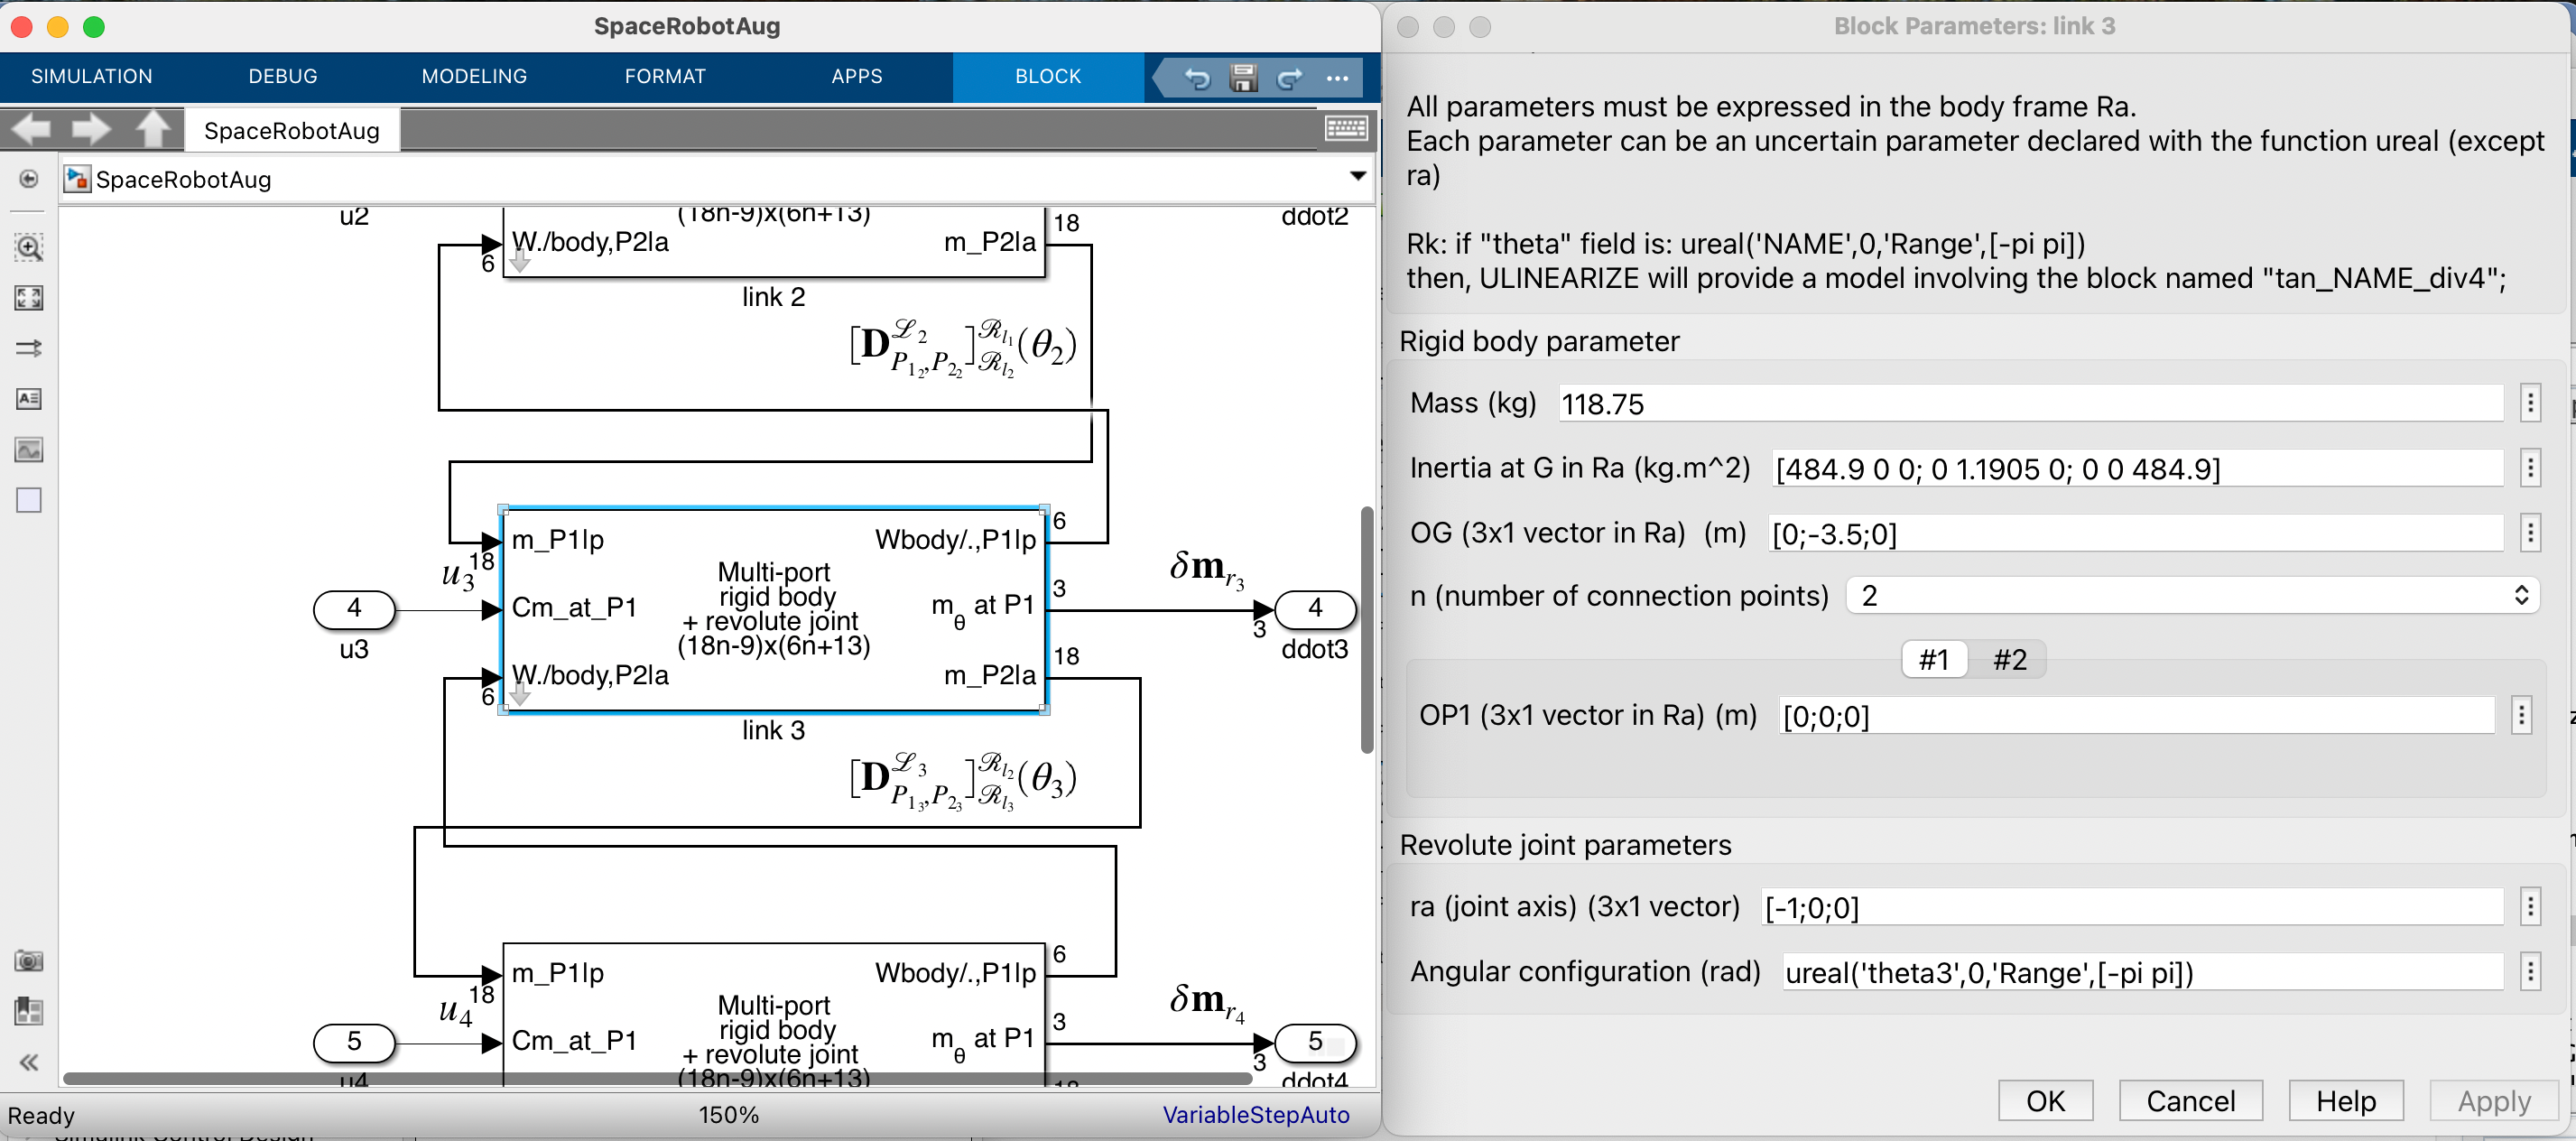

See also:

web DocMultiportRigidBodyRevolute.html -new

## 3. The whole$12\times 12$ dynamic model

The whole model is then described by the following SIMULINK file `SpaceRobot.slx`:

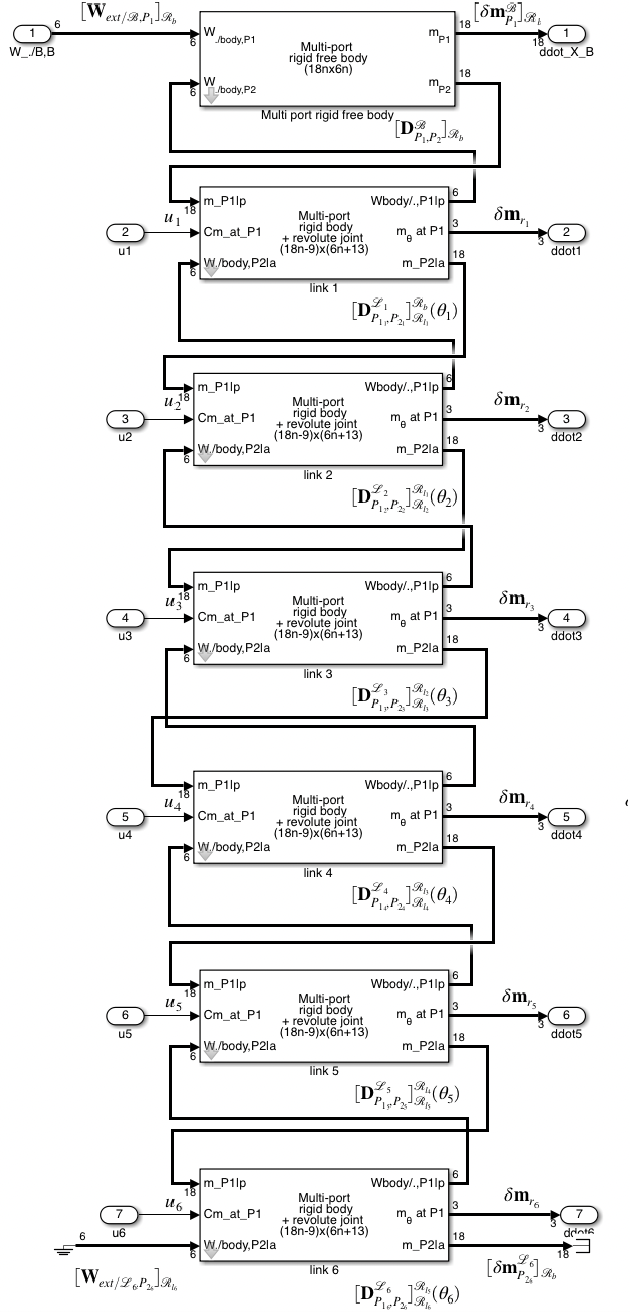

SpaceRobotAug                           % the SIMULINK lile of the model
Gu = ulinearize('SpaceRobotAug')        % 24-th order model.

Uncertain continuous-time state-space model with 36 outputs, 12 inputs, 24 states.
The model uncertainty consists of the following blocks:
  tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
  tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
  tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
  tan_theta4_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
  tan_theta5_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
  tan_theta6_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences


The $12\times 12$ mass matrix can be obtained by the inversion of the transfer from input (forces and torques) to the $12$ acceleration outputs (output number: $[1, 2,3 ,4 5,6, 19, 22,25,28,31,34]$), once the rigid modes ( $24$ poles at $0$) are reduced using a minimal realization:

Mu = inv(sminreal(Gu([1:6 19 22 25 28 31 34],:)))

Uncertain continuous-time state-space model with 12 outputs, 12 inputs, 0 states.
The model uncertainty consists of the following blocks:
  tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
  tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
  tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
  tan_theta4_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
  tan_theta5_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
  tan_theta6_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences


This mass matrix depends on 6 uncertain parameters $\sigma_{4_i}=\tan\frac{\theta_i}{4}$, $i=1,\cdots 6$ with an occurence of $16$ for each parameter.

## 4. First analyses

The $12\times 12$ mass matrix in the nominal configuration:

M0=Mu.NominalValue

M0 =
 
  D = 
                ddot_X_B(1)  ddot_X_B(2)  ddot_X_B(3)  ddot_X_B(4)  ddot_X_B(5)
   W_.//B,B(1)         1387            0            0            0          566
   W_.//B,B(2)            0         1387    6.515e-13         -566            0
   W_.//B,B(3)            0    3.278e-13         1387        -2953            0
   W_.//B,B(4)            0         -566        -2953    3.557e+04            0
   W_.//B,B(5)          566            0            0            0         1502
   W_.//B,B(6)         2953            0            0            0         4429
   u1                  2953            0            0            0         4429
   u2                     0    3.783e-12         2953   -3.408e+04            0
   u3                     0    1.767e-12         1205   -1.592e+04            0
   u4                     0    1.458e-13         89.6        -1313            0
   u5                  38.4            0            0            0         57.6
   u6            -3.665e-1

The $6\times 6$ mass matrix of the robotic arm when the chaser is clamped on the inertial frame (in the nominal configuration):

M0(7:12,7:12)

ans =
 
  D = 
         ddot1(1)    ddot2(1)    ddot3(1)    ddot4(1)    ddot5(1)    ddot6(1)
   u1   3.408e+04           0           0           0       572.2  -2.929e-16
   u2           0   3.408e+04   1.592e+04        1313           0           0
   u3           0   1.592e+04        8206       739.6           0           0
   u4           0        1313       739.6       112.4           0           0
   u5       572.2           0           0           0       33.04  -4.055e-18
   u6   -3.14e-16           0           0           0  -5.273e-18        0.34
 
Static gain.



The $6\times 6$ mass matrix of the robotic arm (in the nominal configuration) when the chaser is free to move can be computed from the inverse dynamic model `Gu `between the $6$ joint accelerations (output number: $[19, 22,25,28,31,34]$)  and the $6$ joint torques, considering that the 6 first inputs (i.e. the wrench appled on the chaser) are null:

inv(sminreal(Gu.NominalValue([19 22 25 28 31 34],7:12)))

ans =
 
  D = 
        ddot1(1)   ddot2(1)   ddot3(1)   ddot4(1)   ddot5(1)   ddot6(1)
   u1      644.8          0          0          0      12.63    0.02836
   u2          0       1212      582.5      48.96          0          0
   u3          0      582.5       1022        146          0          0
   u4          0      48.96        146      63.28          0          0
   u5      12.63          0          0          0      23.32  -0.005118
   u6    0.02836          0          0          0  -0.005118     0.3399
 
Static gain.



### Worst-case analysis:

The inverse dynamic model `Gu` and the direct dynamic model `Mu` are fully compatible with the robust control toolbox. To illustrate worst-case analysis, let us consider the computation of the angular configuration $\mathbf\theta_{wc}$ leading to the maximal inertia seen by the chaser around its ( $O_b,\mathbf y_b$ ) axis, that is to say, the $5$-th input/output chanel of the model `Mu`:


$$\mathbf\theta_{wc}=\arg\max_{\mathbf \theta}|[\mathbf D_B^{\mathcal{S}}(5,5)]_{\mathcal R_b}(\mathbf\theta)|$$


Obviously, considering the system geometric configuration depicted in the first  Figure, the inertia around the ($O_b,\mathbf y_b$) axis is maximal for : $\mathbf\theta_{wc}=[0\quad\pi/2\quad 0\quad 0\quad 0\quad 0]^T$.

It is a little bit disapointing to see that the function `wcgain` fails to find this worst-case. Indeed:

[WCG,WCU] = wcgain(Mu(5,5))

WCG = struct with fields:
           LowerBound: 2.9468e+04
           UpperBound: Inf
    CriticalFrequency: 0


WCU = struct with fields:
    tan_theta1_div4: 0.2029
    tan_theta2_div4: 0.1151
    tan_theta3_div4: 0.2029
    tan_theta4_div4: 0.2029
    tan_theta5_div4: 0.0262
    tan_theta6_div4: -0.0457


One can use the "home-made" function `wcpeak` to recover (approximatively) the obvious answer:

[WCG,WCU] = wcpeak(Mu(5,5))

WCG = struct with fields:
           LowerBound: 4.4431e+04
    CriticalFrequency: 0
           UpperBound: 4.6707e+04


WCU = struct with fields:
    tan_theta1_div4: 0
    tan_theta2_div4: 0.4123
    tan_theta3_div4: 0.0027
    tan_theta4_div4: 0.0027
    tan_theta5_div4: 0
    tan_theta6_div4: 0


Note that $\theta_1$ and $\theta_6$ do not impact this worst-case configuration.

The worst case inertia is:

usubs(Mu(5,5),WCU)

ans =
 
  D = 
                ddot_X_B(5)
   W_.//B,B(5)    4.443e+04
 
Static gain.



## 5. Flexible robotic arm on the chaser

The flexibility of links $\mathcal L_2$ and $\mathcal L_3$(with a very long aspect ratio) is now taken into account. They are modelled as uniform aluminium beams with circular cross section (radius: $0.1\,m$, thickness: $0.01 m$) to have the same mass/inertia than the rigid links used in the previous model. 

The 6 d.o.f. of a flexible beam $\mathcal L_i$ is modelled with a TITOP "superelement" embedded in the bock `2 ports flexible beam` of the sub-library `6 dof bodies` of the `SDTlib` and/or in the block  `TITOP flexible beam+revolute joint`  (which takes into account a revolute joint at one tip of the beam) in the library` Predefined subsystems`. 

This model is expressed in the local frame $\mathcal R_{l_i}=(\mathbf x_{l_i}, \mathbf y_{l_i}, \mathbf z_{l_i})$ of the beam assuming that $\mathbf x_{l_i}$ is along the beam axis (see next Figure) . This model considers 4 bending modes in the plane ( $\mathbf x_{l_i},\mathbf y_{l_i}$), 4 bending modes in the plane ( $\mathbf x_{l_i},\mathbf z_{l_i}$ ), 1 torsion mode around $\mathbf x_{l_i}$ and one traction mode along $\mathbf x_{l_i}$.

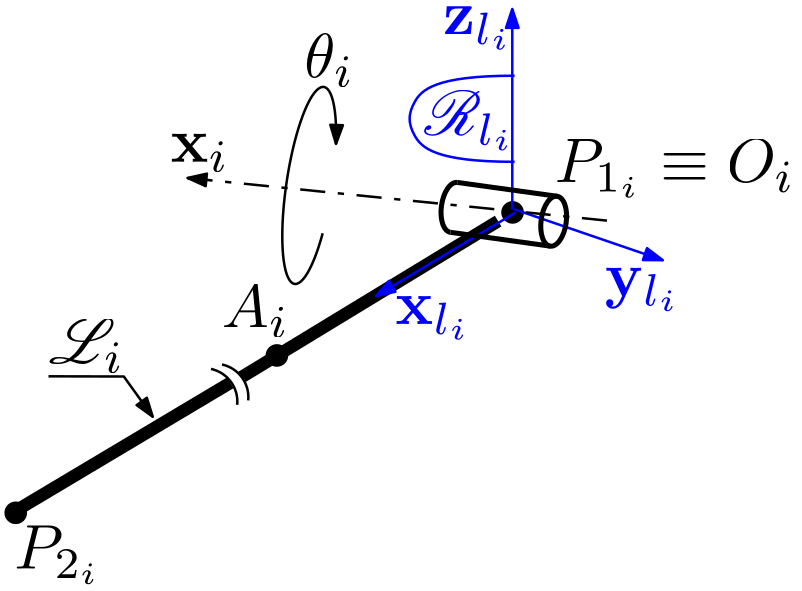

See also: 

web DocBeam.html -new
web DocBeamRevolute.html -new

Since $\mathcal R_{l_2}$ and $\mathcal R_{l_3}$ are no more aligned with $\mathcal R_b$, the DCM $\mathbf P_{l_2/l_1}=\left[\begin{array}{ccc}0 & 1 & 0 \\ -1 & 0 & 0\\ 0 & 0 & 1\end{array}\right]$ must be taken into account (see following Figure).

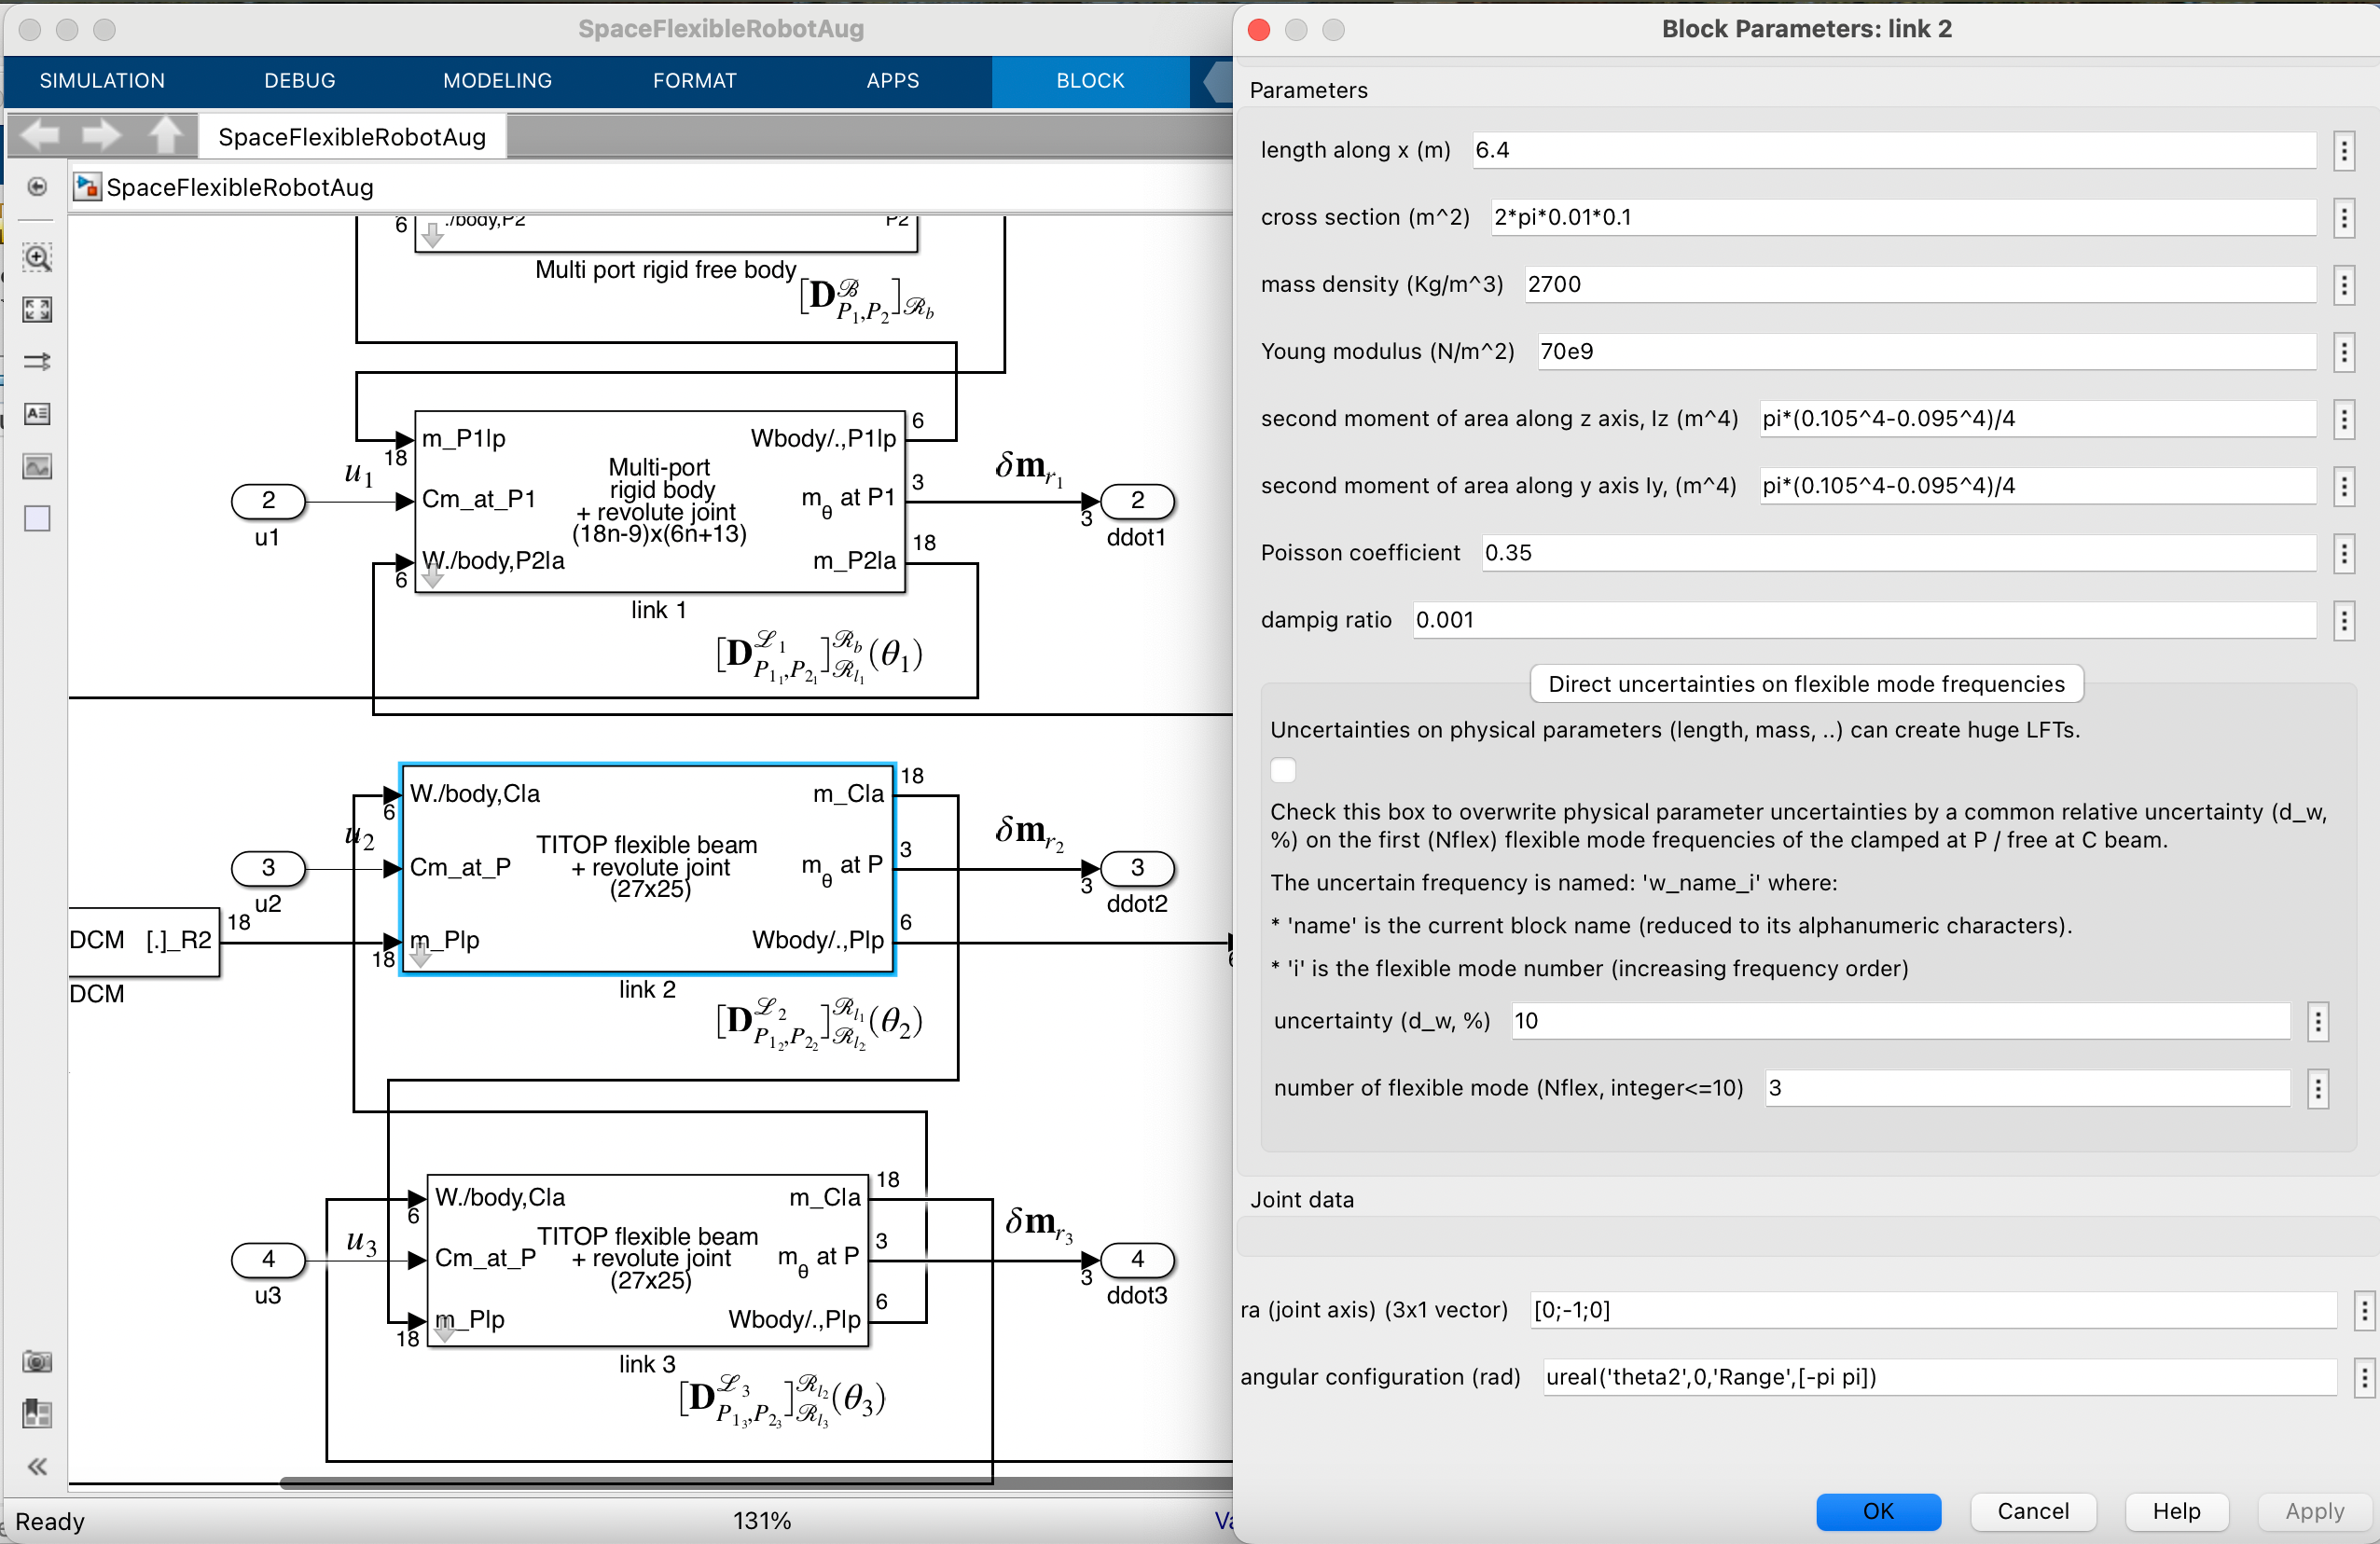

SpaceFlexibleRobotAug
Guf=ulinearize('SpaceFlexibleRobotAug');

The $12\times 12$ **dynamic** mass matrix can be obtained by the inversion of the transfer from input (forces and torques) to the $12$ acceleration outputs (output number: $[1, 2,3 ,4 5,6, 19, 22,25,28,31,34]$), once the rigid modes ( $24$ poles at $0$) are reduced using a minimal realization:

Muf = inv(sminreal(Guf([1:6 19 22 25 28 31 34],:)))

Muf =

  Uncertain continuous-time state-space model with 12 outputs, 12 inputs, 40 states.
  The model uncertainty consists of the following blocks:
    tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta4_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta5_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta6_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences

Type "Muf.NominalValue" to see the nominal value, "get(Muf)" to see all properties, and "Muf.Uncertainty" to interact with the uncertain elements.



This model, once the $24$  poles at $0$ are removed, is $40$-th order model with $10$ flexible modes per flexible links.

One can check that the DCgains of the (dynamic) mass matrices are almost the same ones in the rigid case and in the flexible case (with the rounding errors in the computation of the inertia and mass) for any parametric configurations (the maximal relative error is around $-67 dB\approx5.\;10^{-4}$).

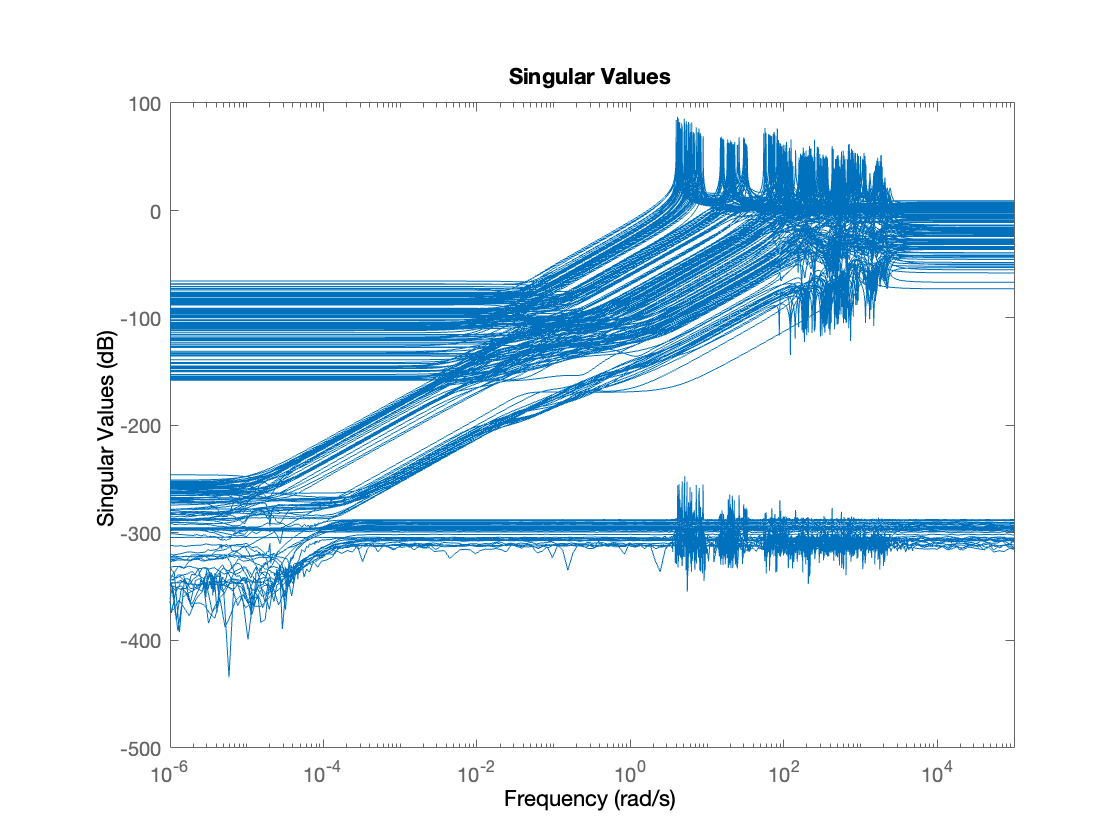

figure
sigma(eye(12)-Muf/Mu)

The next Figure compares the frequency domain response (singular values plot)  of the $6\times 6$ mass matrix seen from arm joints when:

- the chaser is locked on the inertial frame, i.e. when the 6 acceleration inputs $\ddot\mathbf x^{\mathcal B}_{P_1}=\mathbf 0$ (blue plot)

- the chaser is free to move, i.e. when the 6 inputs $\mathbf W_{ext/\mathcal B,P_1}=\mathbf 0$ (red plot),

in the nominal configuration.

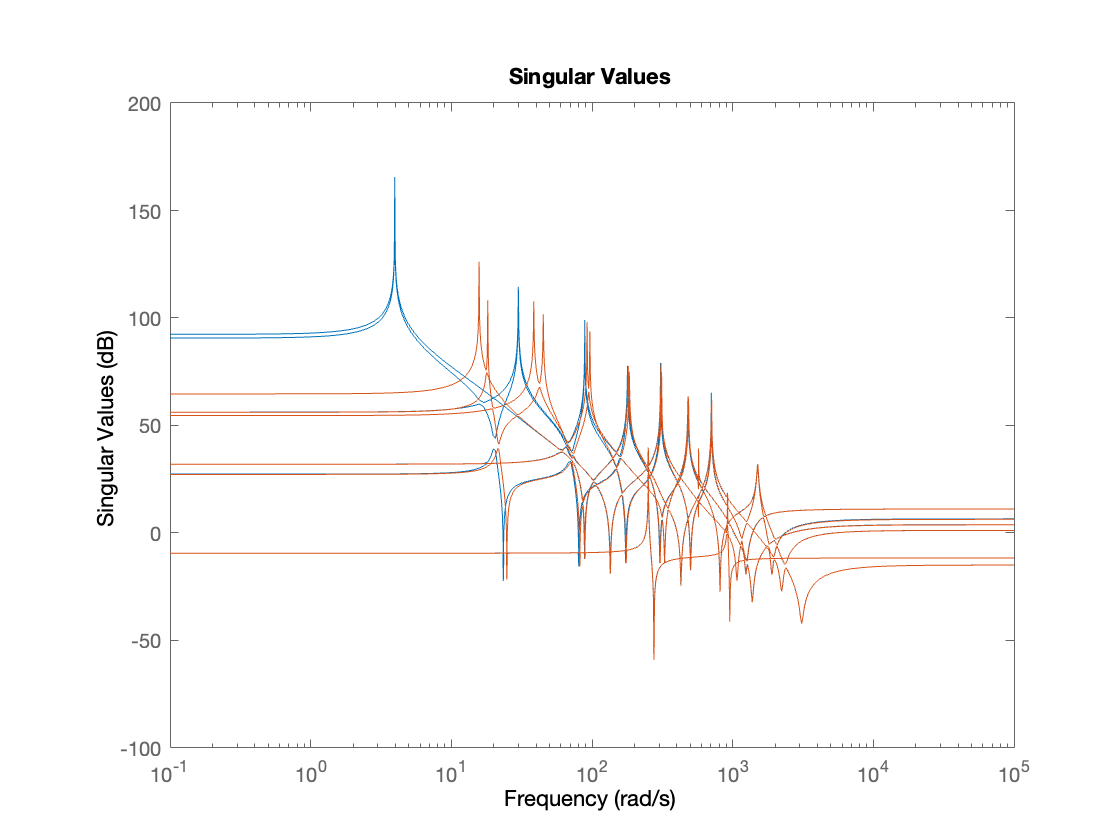

figure
sigma(Muf.NominalValue(7:12,7:12),inv(Guf.NominalValue([19 22 25 28 31 34],7:12)))

The next figure plots the same response for a set of random parametric confgurations:

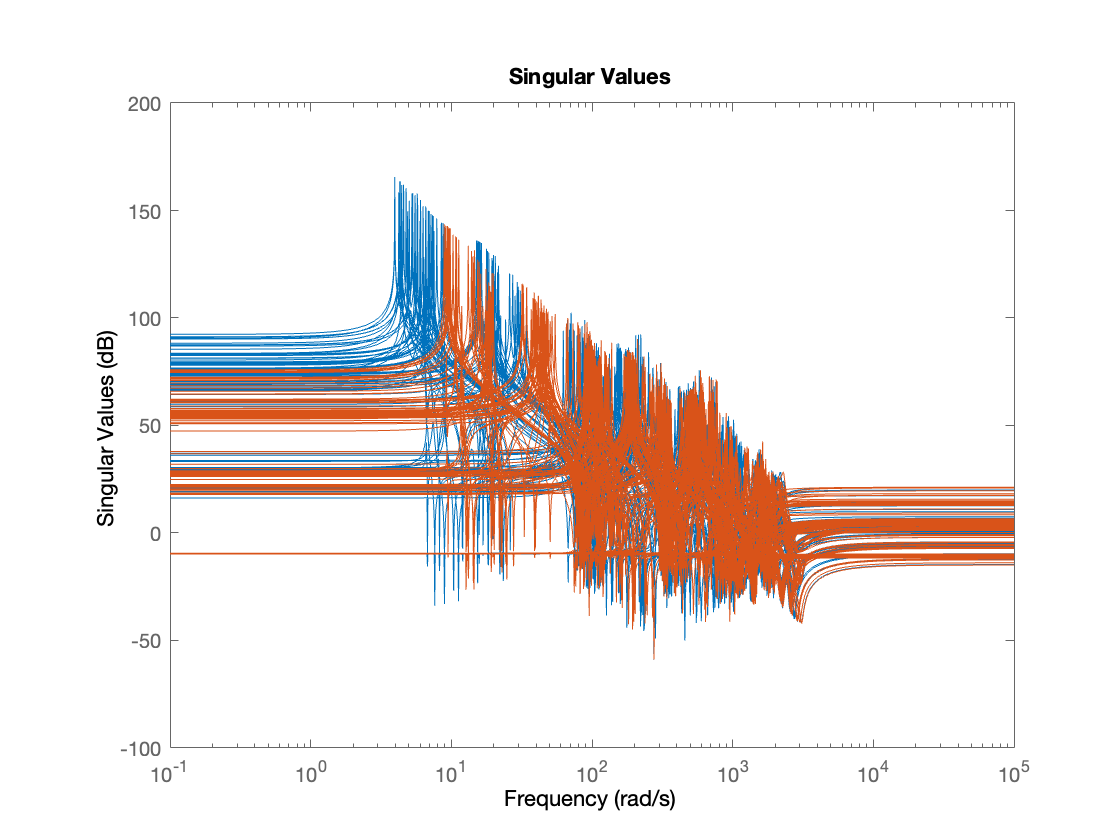

figure
sigma(Muf(7:12,7:12),inv(Guf([19 22 25 28 31 34],7:12)))

## 6. Chaser + flexible robotic arm + flexible target

The previous robotic arm graps now a target $\mathcal   T$ which corresponds to the spacecraft (with 2 flexible solar arrays) studied in the [***tutorial 2***](matlab:open('../Tutorial2/tutorial2.html')). The end effector of the arm (point $P_{2_6}$) holds $\mathcal T$ by the point $P_1$ (renamed $P_{1_t}$) of the target main body (see  [***tutorial 2***](matlab:open('../Tutorial2/tutorial2.html'))) in the configuration described in the following Figure:

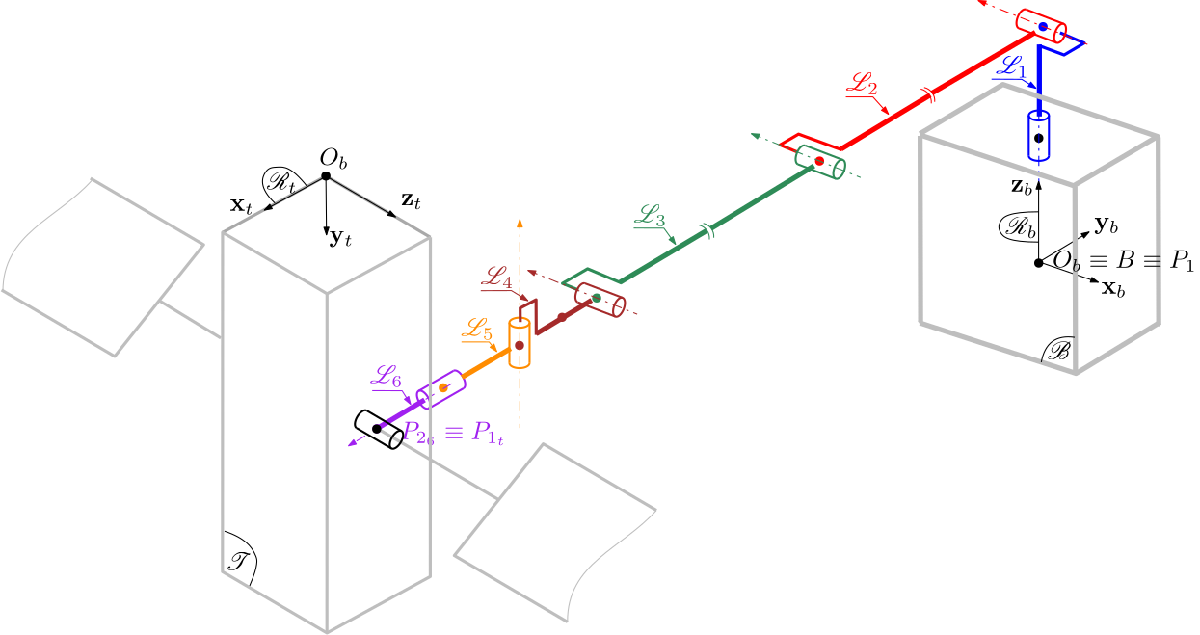

The DCM from the target frame $\mathcal R_t$ to the end-effector frame $\mathcal R_{l_6$ is: $\mathcal P_{t/l_6}=\left[\begin{array}{ccc}0 & 0 & 1 \\ -1 & 0 & 0\\ 0 & -1 & 0\end{array}\right]$.

To model the system composed of the chaser, the robotic arm and the target, one can reuse the SIMULINK file developed in the [***tutorial 2***](matlab:open('../Tutorial2/tutorial2.html')) as the subsystem `Target `in positive feedback on the subsystem `Chaser+Arm `developed in the previous section. The whole block diagram is then depicted in the following Figure:

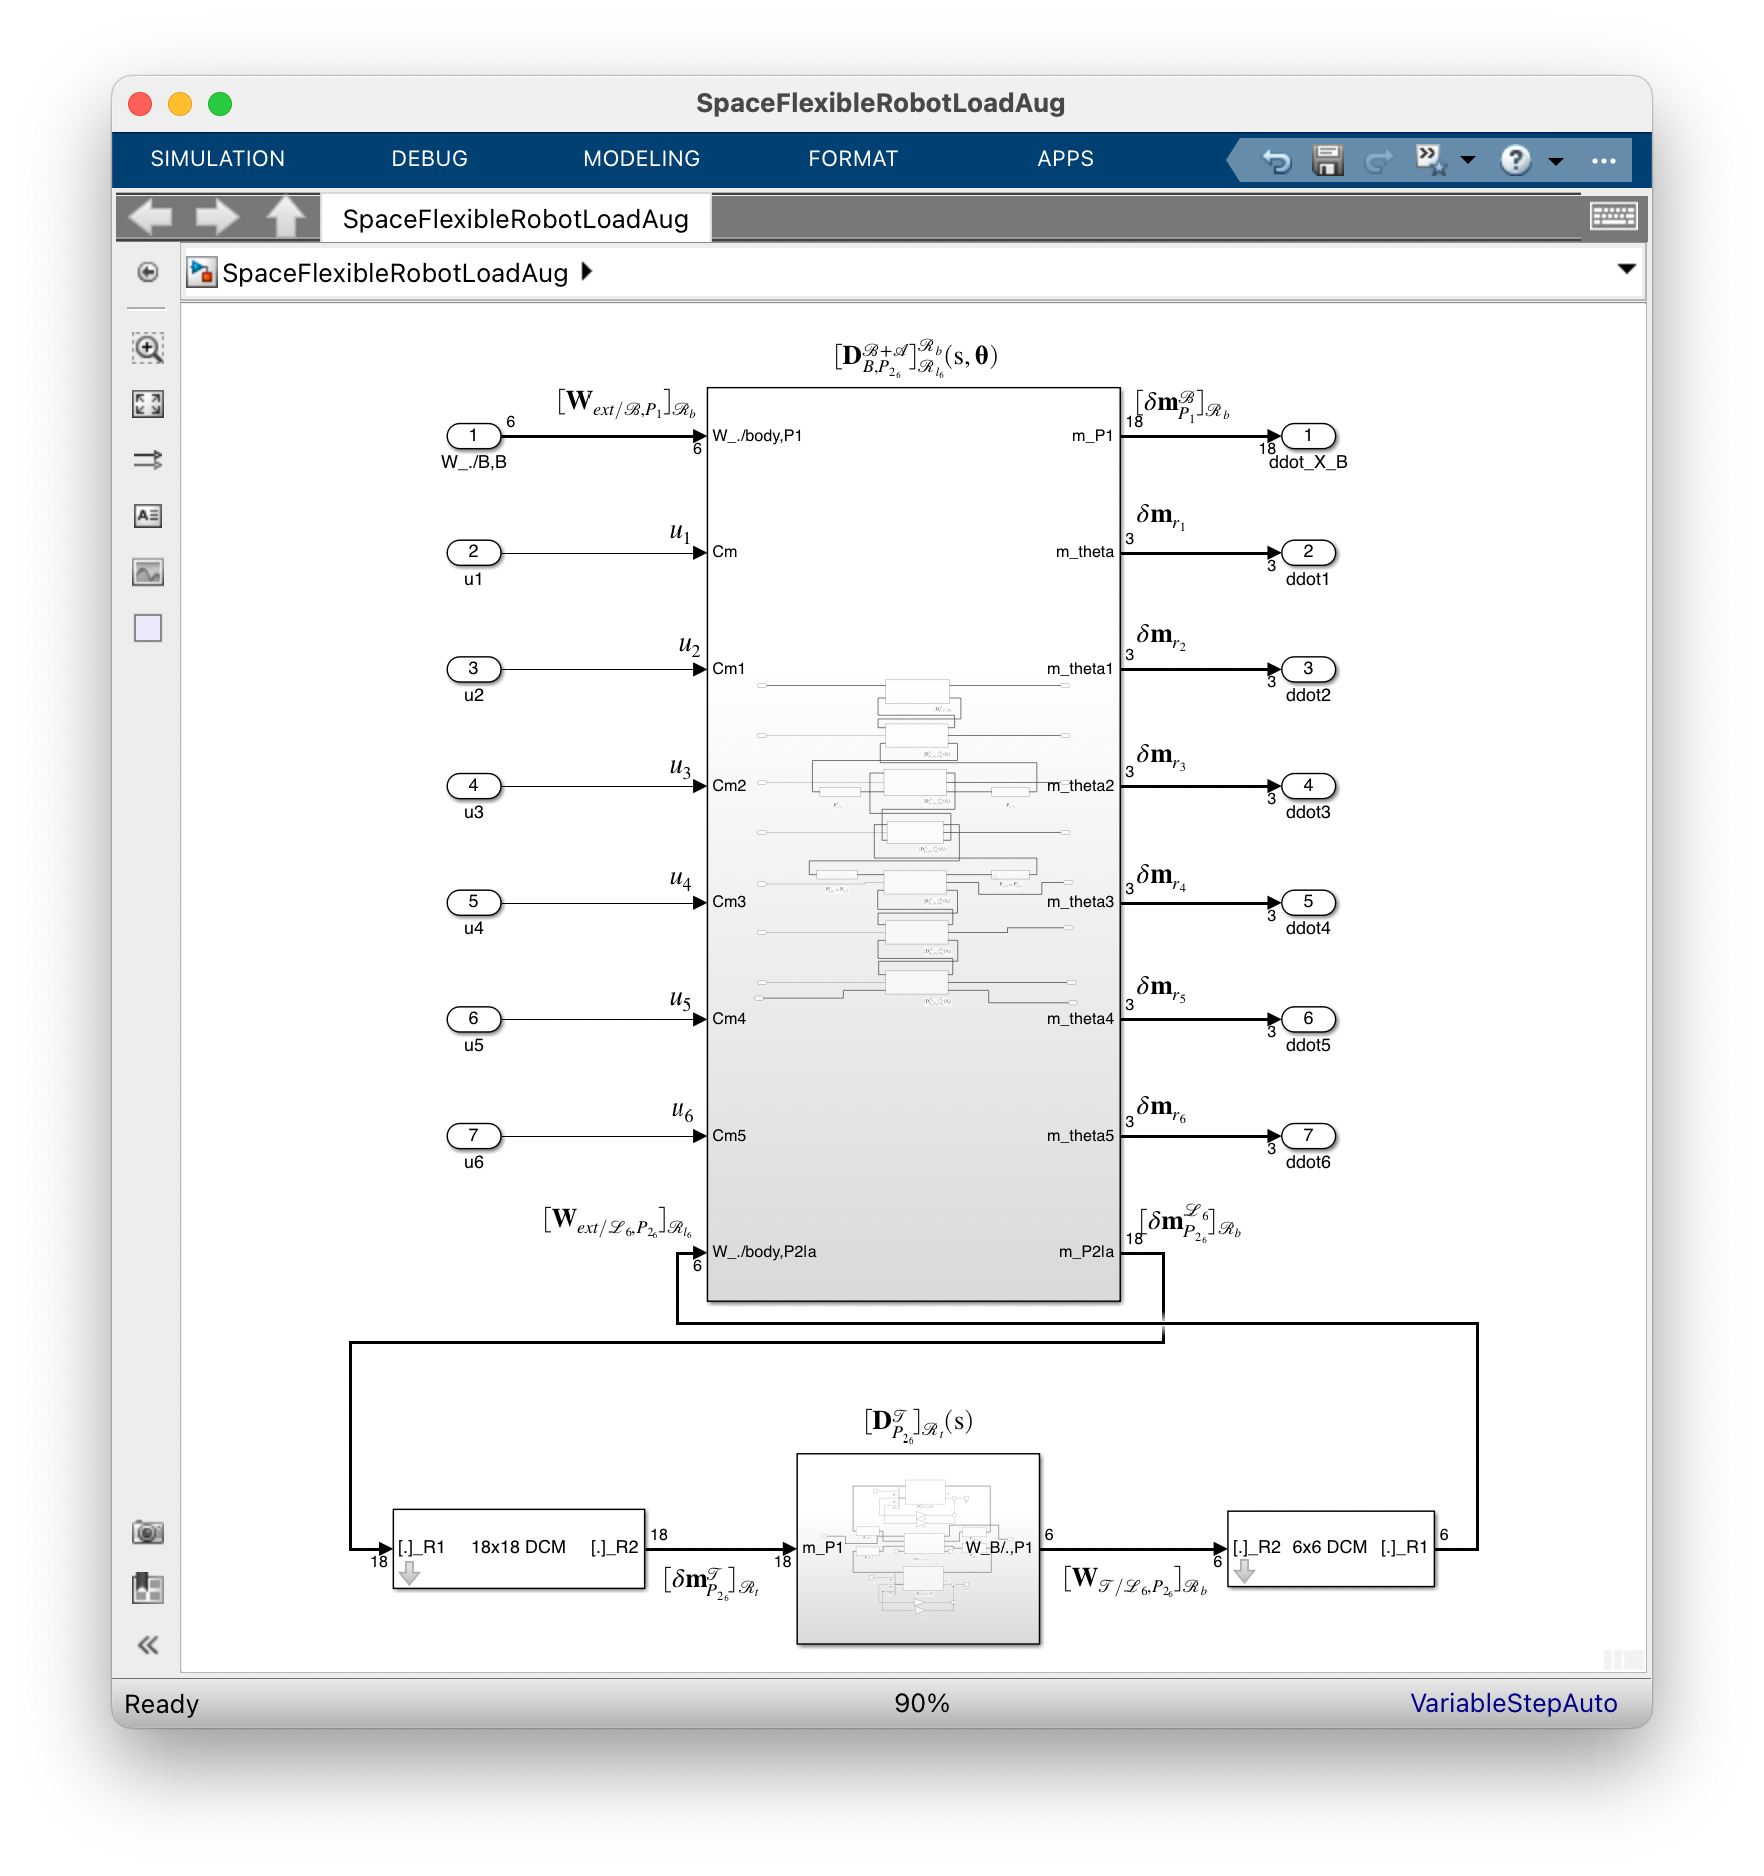

The target model $[\mathbf D_{P_{1_t}}^{\mathcal T}]_{\mathcal R_t}(\mathrm s)$ is the model  of the target between the [motion vector](matlab:open('../SDTfct/doc_SDTlib/doc_BODIES/doc_hub/DocGeneralNotations.html'))  $\delta\mathbf{m}^{\mathcal T}_{P_{1_t}}$ prescribed by the arm end effector at the point $P_{1_t}=P_{2_6}$ (input) and the wrench $\mathbf W_{\mathcal{T/L}_6,P_{1_t}}$applied by the target to the end effector at the point $P_{1_t}=P_{2_6}$. This model is the same than the model used in the [***tutorial 2***](matlab:open('../Tutorial2/tutorial2.html')) but the block `multi port rigid free body` is now changed by `multi port rigid body `block with 4 ports `P1, P2, P3, P4 `corresponding to the points $P_1$ twice (one times for the connection with arm end effector, one times to connect the solar array), $P_2$ and $P_3$.  Finally, the port `P1 `must be declared a sthe parent port since the motion vector at point $P_1$ are imposed by the end effector. The subsystem `Target` is detailled in the following Figure.

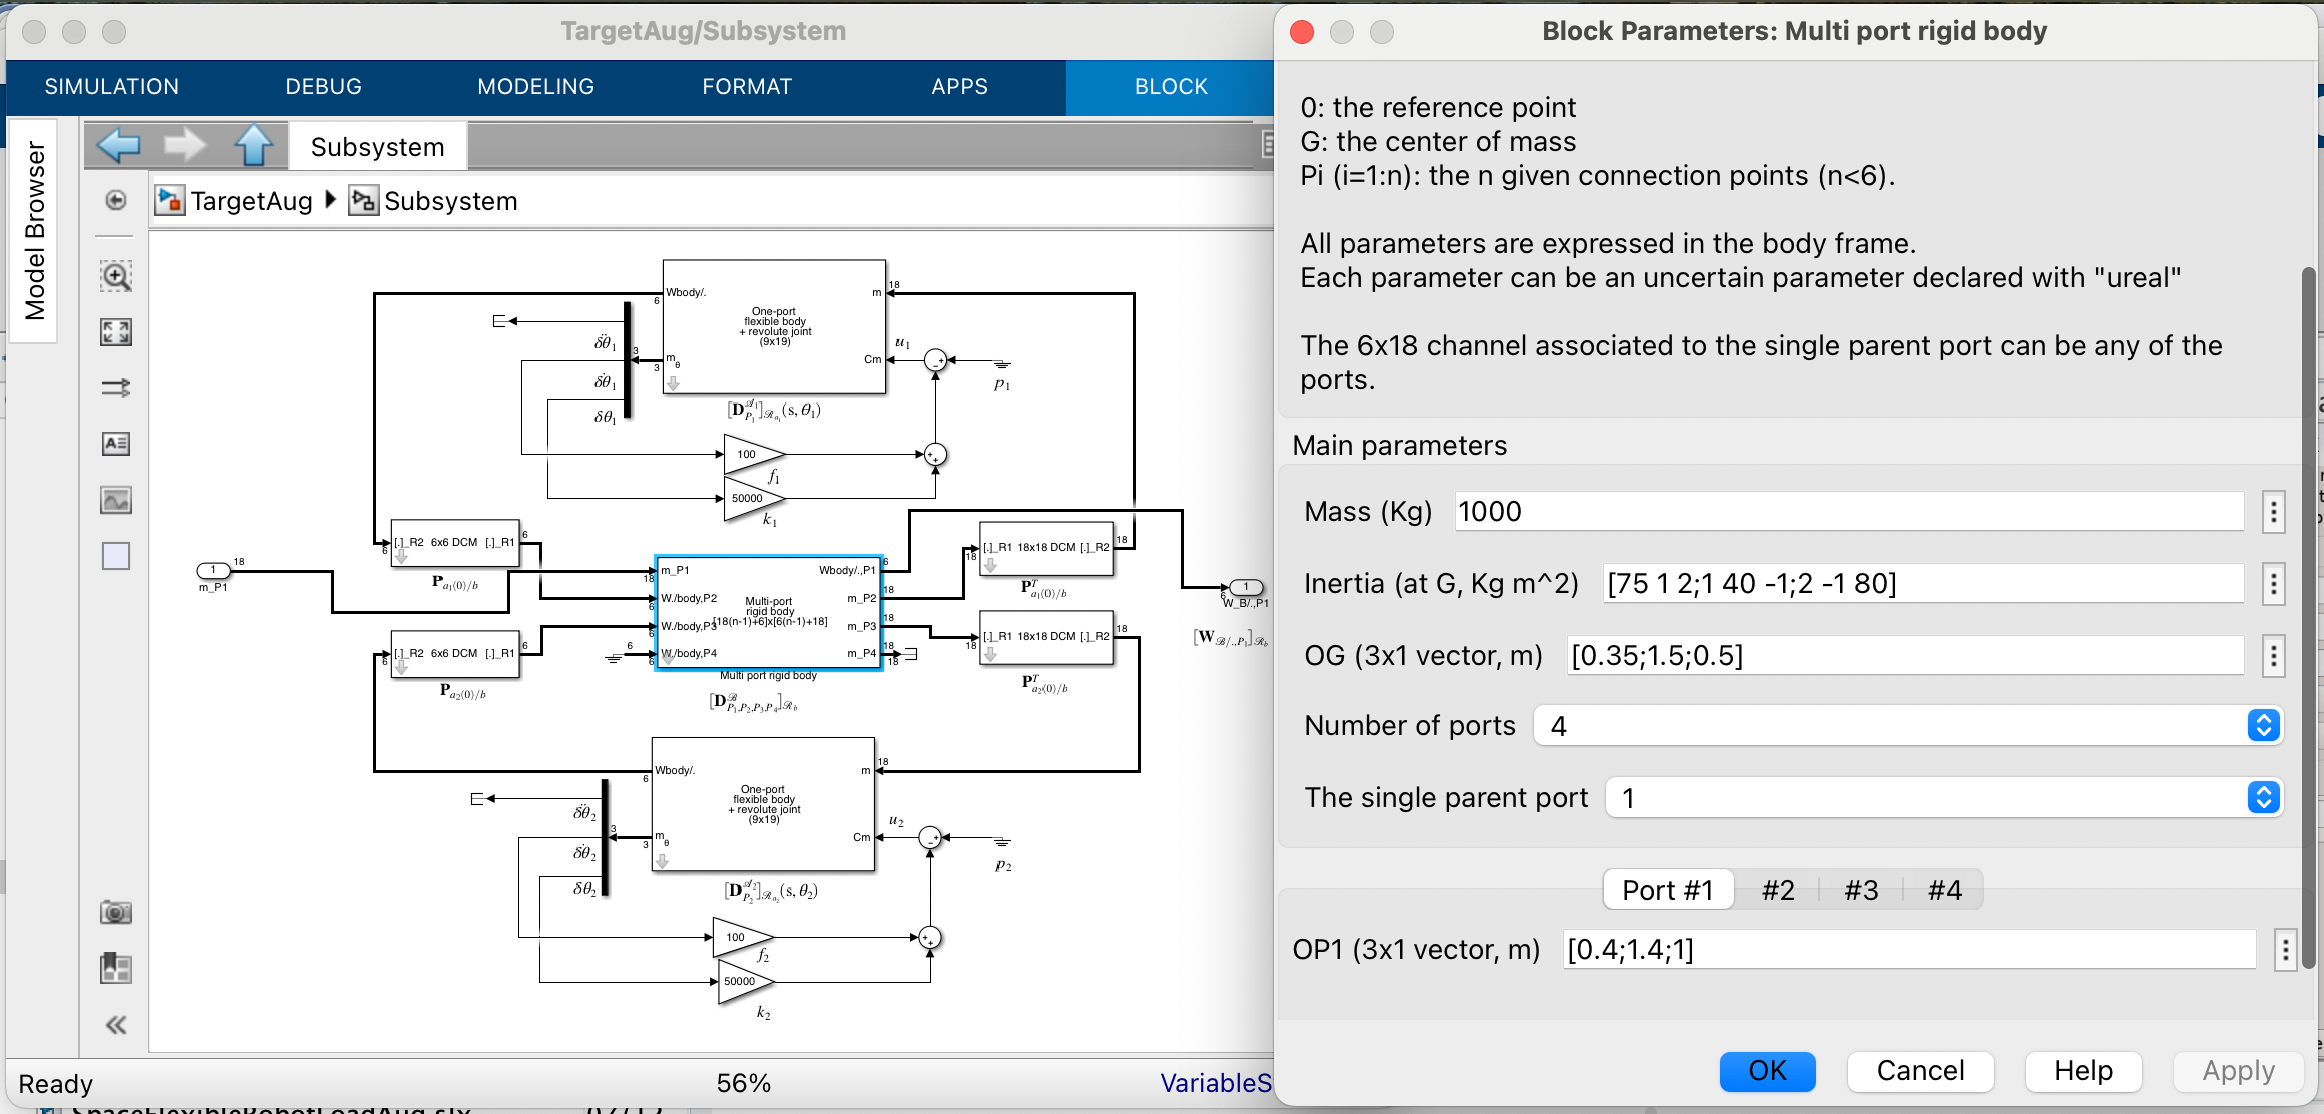

SpaceFlexibleRobotLoadAug
Gufl=ulinearize('SpaceFlexibleRobotLoadAug')

Gufl =

  Uncertain continuous-time state-space model with 36 outputs, 12 inputs, 80 states.
  The model uncertainty consists of the following blocks:
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences
    tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta4_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta5_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta6_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences

Type "Gufl.NominalValue" to see the nominal value, "get(Gufl)" to see all properties, and "Gufl.Uncertainty" to interact with the uncertain elements.



The model order is now $80$; equal to the chaser+arm model order ( $40$ flexible state $+$ 24 rigid states ) $+$ the target model order ( $16$ ). The model depends on 7 parameters: the 6 arm joint angular configurations and the angular configuration of the target solar arrays.

### First analyzes

The next figure plots the pole/zero map for various parametric configurations and for the nominal configuration (in  red):

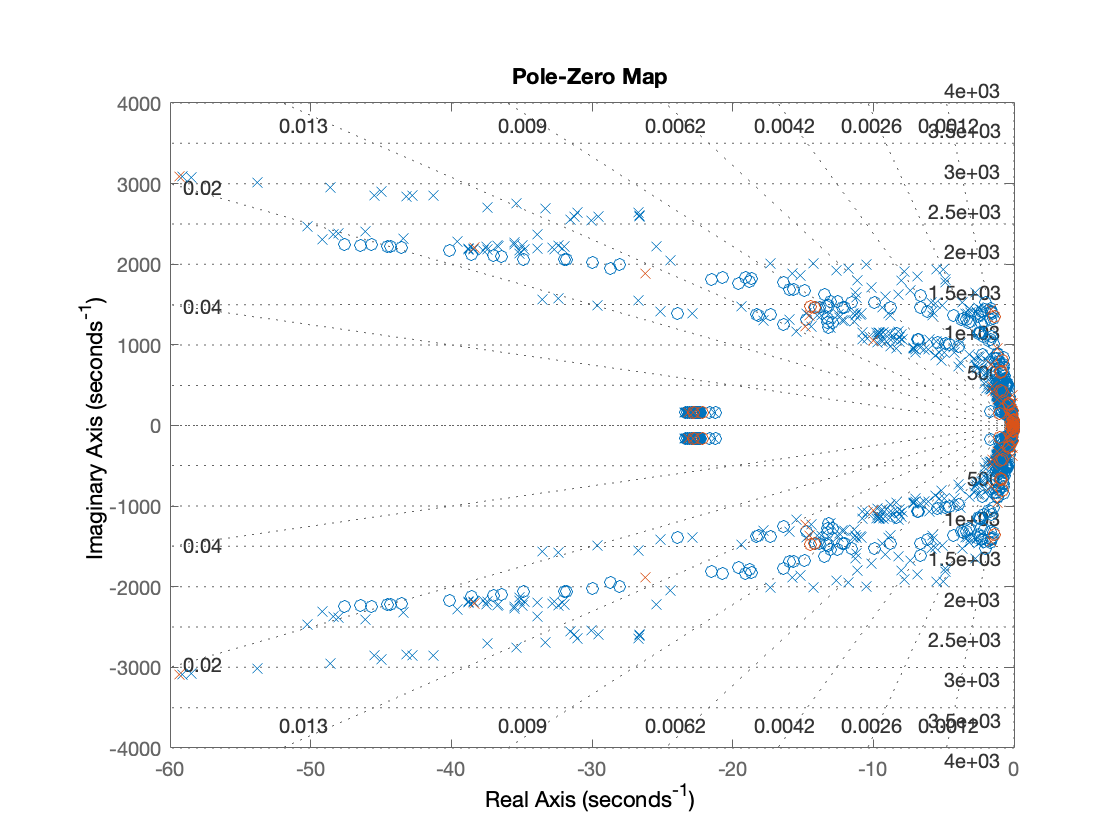

figure
pzmap(Gufl,Gufl.NominalValue)
sgrid

Although all the modes are badly damped, they are of course always stable for any parametric configurations since the model is the result of the connection of passive flexible bodies. Nethertheless, it is surprising to see that (around $-22\pm 150j$), 2 modes are damped up to $0.15$. 

The dynamic couplings between the various bodies and their flexible modes depend on the boundary condition applied by the joint controller (not still designed). They can be illustrated on the frequency-domain response, in the nominal configuration, of the transfer between the 3 torques applied on the chaser $[\mathbf W_{ext/\mathcal B,P_1}]_{\mathcal R_b}(4:6)$ to control its attitude and the 3 angular accelerations of the chaser $[\delta\mathbf m^\mathcal B_{P_1}]_{\mathcal R_b}(4:6)$ (i.e. the channels 4 to 6 of the model `Gufl`):

- when the 6 arm joints are free. The response is in blue in the next Figure,

- when the 6 arm joints are locked. The response is in red in the next Figure. The model when the joints are locked (i.e.: $\ddot\theta_i=0,\;i=1,\cdots,6$ ) is simply obtained by the inversion of the channel 7 to 12 of the model `Gufl` thanks to the function `invio`.

See also:

web docInvio.html -new

Since only the tranfers from wrench to acceleration are considered, one can ignore the outputs relative to the velocities and positions of the main body and of the revolute joint and reduce the rigid modes using a minimal realization.

Guflr=sminreal(Gufl([1:6 19 22 25 28 31 34],:))

Guflr =

  Uncertain continuous-time state-space model with 12 outputs, 12 inputs, 56 states.
  The model uncertainty consists of the following blocks:
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences
    tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta4_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta5_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta6_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences

Type "Guflr.NominalValue" to see the nominal value, "get(Guflr)" to see all properties, and "Guflr.Uncertainty" to interact with the uncertain elements.



The frequency domain response in the frequency band: $1-1000\,rd/s$:

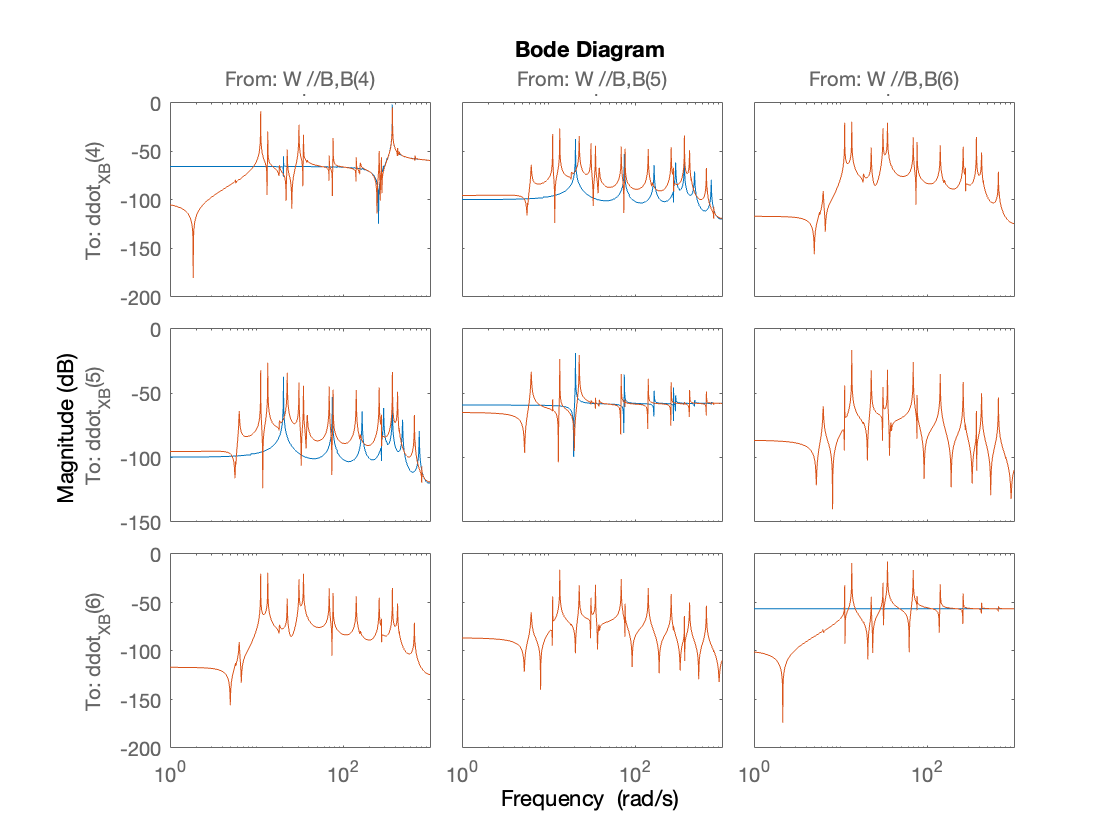

Guflr_lock=invio(Guflr,7:12);
figure
bodemag(Guflr.NominalValue(4:6,4:6),Guflr_lock.NominalValue(4:6,4:6),{1,1000})

## 7. Remark

- the SDT is used to compute the linear dynamic model of multi-body systems around a given geometric configuration. This geometric configuration is  considered as a varing parameter. Geometric constraints, for instance to avoid colision between the arm and the chaser, are not considered in this toolbox.